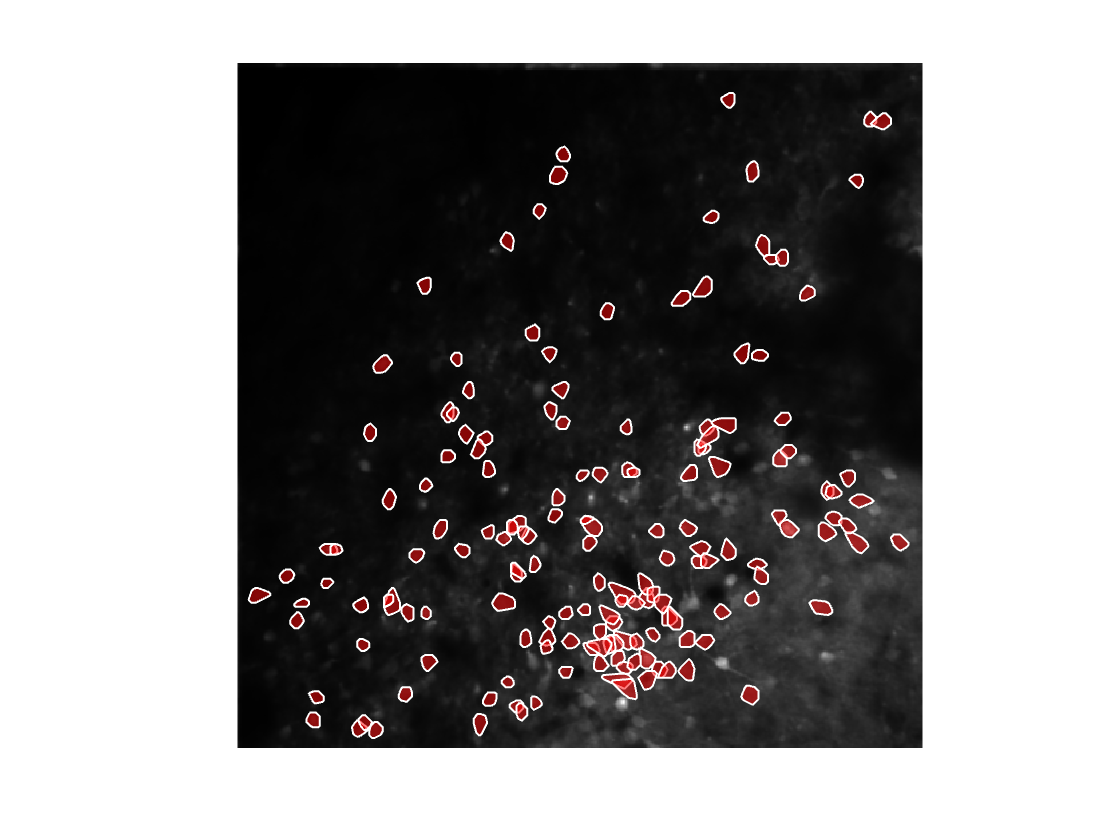

load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_24_16_42_06P2M_411582_230320_plane1_2023_04_05.17-57-09assemblysce6last/brainbow.mat')
% fig = figure('visible','off');
figure
colormap ("gray")
imagesc(calcium)
% title (['assembly ' num2str(num) ':' , num2str(numel(cell2mat(assembly(num)))) , ' cells'],'Position', [0, 1.3, 0],'FontSize',16);
hold on
for n=DC
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    patch(x, y,'red','FaceAlpha', 0.5,'EdgeColor','w','LineWidth',1)
    % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    % plot(x, y, '.', 'MarkerSize', 4,"Color",col);

end
    axis off
    axis image
    hold off

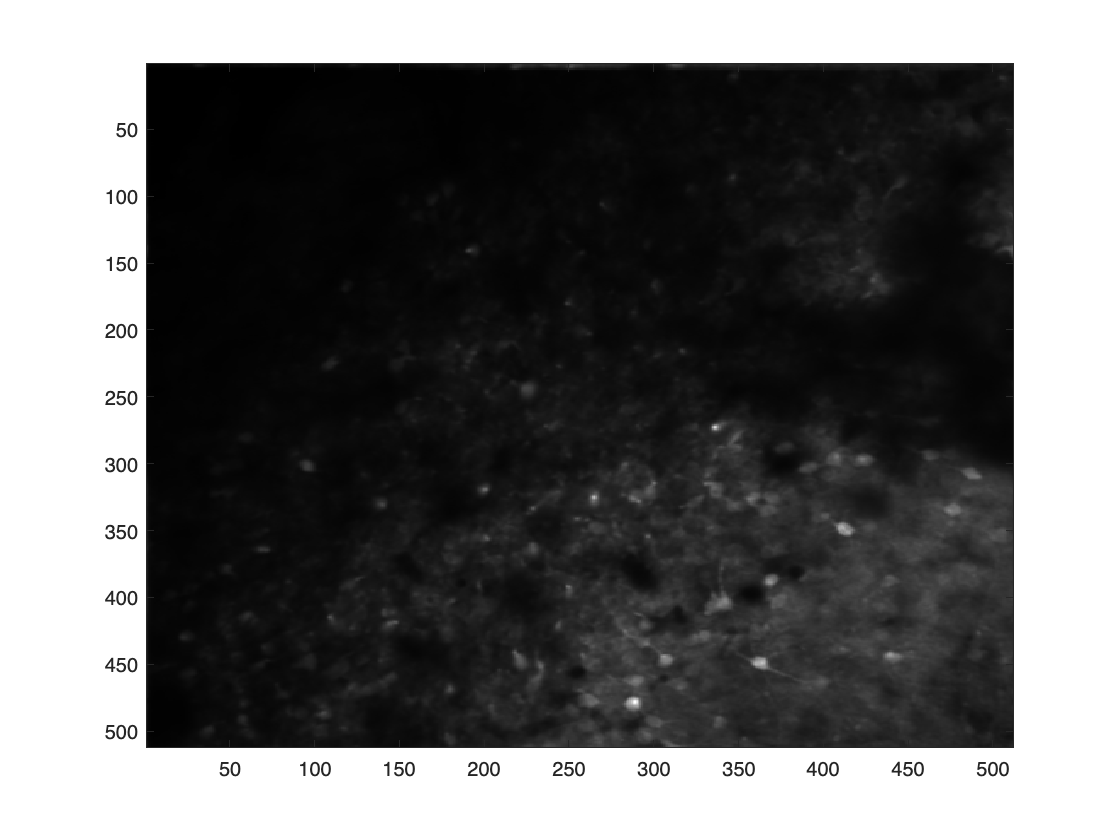

figure
imagesc(calcium)
colormap ("gray")

for n=DC2  
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    patch(x, y,'green','FaceAlpha', 0.5,'EdgeColor','w','LineWidth',1)
    % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    % plot(x, y, '.', 'MarkerSize', 4,"Color",col);

end

Unrecognized function or variable 'DC2'.

    axis off
    axis image
    hold off
figure
imagesc(calcium)
colormap ("gray")
for n=DC3  
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    patch(x, y,'blue','FaceAlpha', 0.5,'EdgeColor','w','LineWidth',1)
    % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    % plot(x, y, '.', 'MarkerSize', 4,"Color",col);

end
    axis off
    axis image
    hold off

% fig = figure('visible','off');
figure
colormap ("gray")
imagesc(calcium)
% title (['assembly ' num2str(num) ':' , num2str(numel(cell2mat(assembly(num)))) , ' cells'],'Position', [0, 1.3, 0],'FontSize',16);
hold on
for n=DC1  
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    patch(x, y,'red','FaceAlpha', 0.5,'EdgeColor','w','LineWidth',1)
    text(max(x),min(y),num2str(n),"FontSize",8,"Color",'w')
    % plot(x, y, '.', 'MarkerSize', 4,"Color",col);

end

for n=DC2  
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    patch(x, y,'green','FaceAlpha', 0.5,'EdgeColor','w','LineWidth',1)
    text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    % plot(x, y, '.', 'MarkerSize', 4,"Color",col);

end

for n=DC3  
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    patch(x, y,'blue','FaceAlpha', 0.5,'EdgeColor','w','LineWidth',1)
    text(min(x),min(y),num2str(n),"FontSize",8,"Color",'w')
    % plot(x, y, '.', 'MarkerSize', 4,"Color",col);

end

axis off
axis image
hold off

TrDC1=TrDC1(xDel1,:);
TrDC2=TrDC2(xDel2,:);
TrDC3=TrDC3(xDel3,:);


TrDC=[TrDC1;TrDC2;TrDC3];

NDC=size(TrDC,1);

figure
subplot(4,1,1)
imagesc(t(1:floor(Nt/4)),1:NDC,TrDC(:,1:floor(Nt/4)),[0 0.5])
hold on
plot(t(1:floor(Nt/4)),NDC-SpBlur(1:floor(Nt/4))/2,'g')
subplot(4,1,2)
imagesc(t(floor(Nt/4):floor(Nt/2)),1:NDC,TrDC(:,floor(Nt/4):floor(Nt/2)),[0 0.5])
hold on
plot(t(floor(Nt/4):floor(Nt/2)),NDC-SpBlur(floor(Nt/4):floor(Nt/2))/2,'g')
subplot(4,1,3)
imagesc(t(floor(Nt/2):floor(3*Nt/4)),1:NDC,TrDC(:,floor(Nt/2):floor(3*Nt/4)),[0 0.5])
hold on
plot(t(floor(Nt/2):floor(3*Nt/4)),NDC-SpBlur(floor(Nt/2):floor(3*Nt/4))/2,'g')
subplot(4,1,4)
imagesc(t(floor(3*Nt/4):Nt),1:NDC,TrDC(:,floor(3*Nt/4):Nt),[0 0.5])
colormap hot
hold on
plot(t(floor(3*Nt/4):Nt),NDC-SpBlur(floor(3*Nt/4):Nt)/2,'g')
xlabel('Time (in s)')


figure
subplot(4,1,1)
imagesc(t(1:floor(Nt/4)),1:NDC,TrDC(xDel,1:floor(Nt/4)),[0 0.5])
hold on
plot(t(1:floor(Nt/4)),NDC-SpBlur(1:floor(Nt/4))/2,'g')
subplot(4,1,2)
imagesc(t(floor(Nt/4):floor(Nt/2)),1:NDC,TrDC(xDel,floor(Nt/4):floor(Nt/2)),[0 0.5])
hold on
plot(t(floor(Nt/4):floor(Nt/2)),NDC-SpBlur(floor(Nt/4):floor(Nt/2))/2,'g')
subplot(4,1,3)
imagesc(t(floor(Nt/2):floor(3*Nt/4)),1:NDC,TrDC(xDel,floor(Nt/2):floor(3*Nt/4)),[0 0.5])
hold on
plot(t(floor(Nt/2):floor(3*Nt/4)),NDC-SpBlur(floor(Nt/2):floor(3*Nt/4))/2,'g')
subplot(4,1,4)
imagesc(t(floor(3*Nt/4):Nt),1:NDC,TrDC(xDel,floor(3*Nt/4):Nt),[0 0.5])
colormap hot
hold on
plot(t(floor(3*Nt/4):Nt),NDC-SpBlur(floor(3*Nt/4):Nt)/2,'g')
xlabel('Time (in s)')

%overlap with assembly
for n=1:numel (assembly)
        intersection{n}=intersect(DC1,cell2mat(assembly(n)));
        inter(n)=numel(intersection{n});
end
figure
for n=1:numel (assembly)
    
    bar (numel(intersection(n)))
    
    % title(['intersection cluster ortho' num2str(n)])
end
hold off

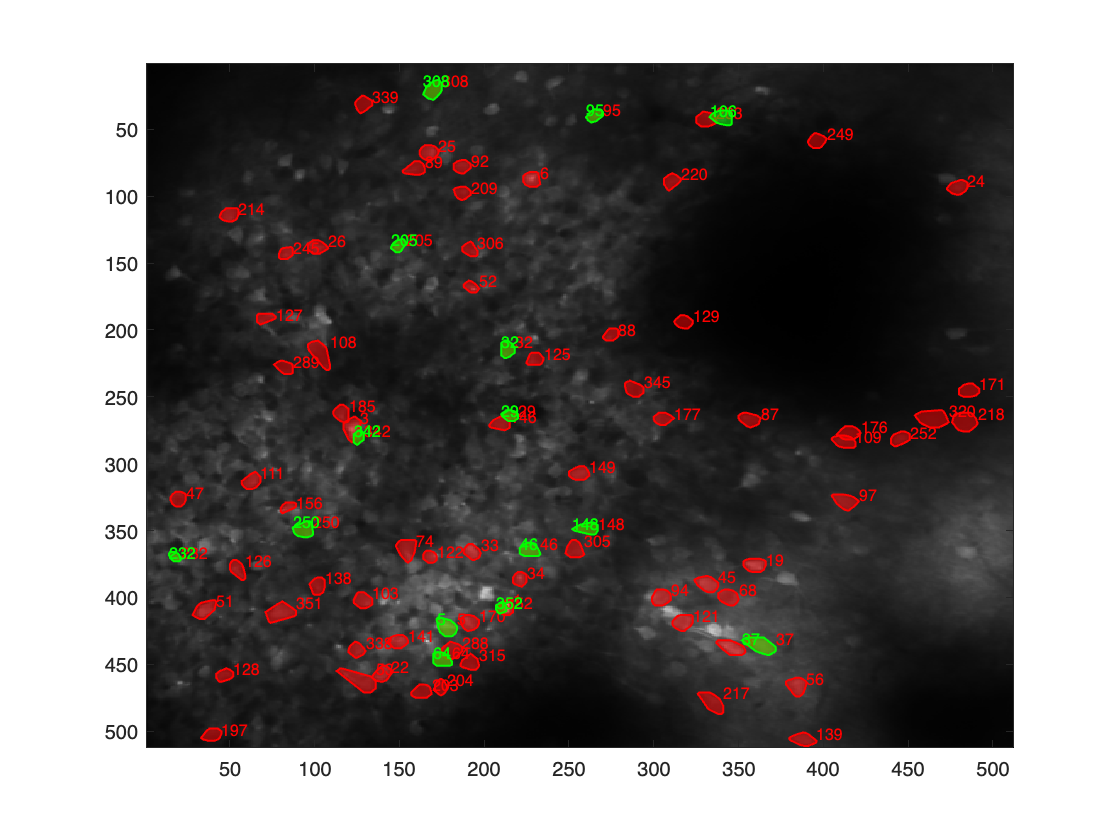

%plot asssembly spatial and sequence


figure
colormap ("gray")
imagesc(calcium)
% title (['assembly ' num2str(num) ':' , num2str(numel(cell2mat(assembly(num)))) , ' cells'],'Position', [0, 1.3, 0],'FontSize',16);
hold on
for n=DC1  
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    patch(x, y,'red','FaceAlpha', 0.5,'EdgeColor','r','LineWidth',1)
    text(max(x),min(y),num2str(n),"FontSize",8,"Color",'red')
    % plot(x, y, '.', 'MarkerSize', 4,"Color",col);

end

for n=cell2mat(assembly(9))  
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    patch(x, y,'green','FaceAlpha', 0.5,'EdgeColor','g','LineWidth',1)
    text(min(x),min(y),num2str(n),"FontSize",8,"Color",'green')
    % plot(x, y, '.', 'MarkerSize', 4,"Color",col);

end